***结构基础***

**(1)条件结构**

if-elseif-else-end语句(if和end必须不能省略)

例子

score=87;
if (score>=90)&&(score<=100)
    res=1;
elseif(score>=80)&&(score<90)
    res=2;
elseif(score>=60)&&(score<80)
    res=3;
elseif(score>=0)&&(score<60)
    res=4;
else
    res=0;
end
res;
%要输出的东西单独打出来
if 2+3
    res=0;
else 
    res=10;
end
res     %res=0  因为2+3=5>0是逻辑值,

res = 0

%               为真则执行为0
if[1,2;0,3]%矩阵中元素有0,则视为逻辑值0
    res=0;
else
    res=10;
end
res

res = 10

A=[1,2;1,3]

A =      1     2
     1     3


if any(A(:))
    res=0;
else
    res=10;
end
res

res = 0

if的嵌套

a=10;
b=20;
c=15;
if a>b
    if a>c
        max=a;
    else
        max=c;
    end
else 
    if b>c
        max=b;
    else
        max=c;
    end
end
max

max = 20

switch-case-otherwise-end语句

其中,开关表达式的计算结果必须是一个数值标量或者是一个字符向量或者字符串,不能是向量或者矩阵

例子

season=randi([1,4])

season = 2

switch season
    case 1
        disp("春季");
    case 2
        disp("夏季");
    case 3
        disp("秋季");
    otherwise
        disp("冬季");
end

夏季


%disp函数:显示变量的值,但是不打印变量名

另一种形式

if season==1
    disp("春季")
elseif season==2
    disp("夏季")
elseif season==3
    disp("秋季")
elseif season==4
    disp("冬季")
end

夏季


***(2)循环结构***

for-end语句(for循环)

用于事先已经知道循环次数的情形

for i=1:5  %从1到5的向量
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

对于矩阵

A=randi([-3,3],2,3)

A =      2    -3     1
     3     3    -3


for i=A
    i   %对列遍历
end

i =      2
     3


i =     -3
     3


i =      1
    -3


输出示例:

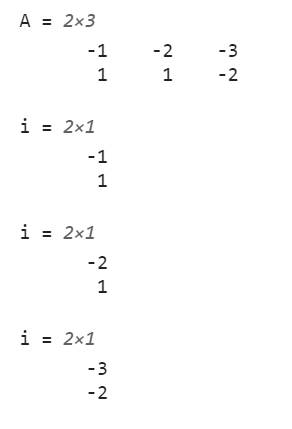

例题:

x=1:6;
res_sum=0;
for i=x
    res_sum=res_sum+i;
end
res_sum

res_sum = 21

闰年计算

leap_year_num=0;
for i=1:9999
    if ((mod(i,4)==0)&&(mod(i,100)~=0))||(mod(i,400)==0)
        %mod(i,4)整除判断
        leap_year_num=leap_year_num+1;
    end
end
leap_year_num

leap_year_num = 2424

while-end循环语句

可以不知道具体循环的次数

示例:斐波那契数列中第一个大于99999

f(1)=1;
f(2)=1;
n=2;
while f(n)<=99999
    n=n+1;
    f(n)=f(n-1)+f(n-2);
end
n

n = 26

f(n)

ans = 121393

对于无限循环,在命令行窗口中按下Ctrl+C结束进程

% while 1
%     disp("sixunhuan ");
% end

while后面可以使用0或者1逻辑值

i=5;
while i
    i
    i=i-1;
end

i = 5

i = 4

i = 3

i = 2

i = 1

%利用逻辑值1或者0来判断是否继续进行程序

break  continue

只能用于for或者while

break:立即退出循环

continue:跳过当前循环剩余部分进行下一次循环

例1(奇数)

for i=1:10
    if mod(i,2)==0
    else
        i
    end
end

i = 1

i = 3

i = 5

i = 7

i = 9

例2(奇数)

for i=1:10
    if mod(i,2)==0
        continue
    end
    i
end

i = 1

i = 3

i = 5

i = 7

i = 9

例3(质数)

n=135389;
is_prime=1;
for i=2:n-1
    if(mod(n,i)==0)
        is_prime=0;
        break;
    end
end
if is_prime==0
    disp("是素数");
else
    disp("不是素数");
end

不是素数


当存在循环的嵌套时

for i=1:2
    for j=1:3
        if j<=i
            i
            j
        else
            break
        end
    end
end

i = 1

j = 1

i = 2

j = 1

i = 2

j = 2

练习:二分法

a=6;
b=10;
eps=1e-8;   %取误差
while 1
    c=(a+b)/2;
    fc=c^3-8*c^2+c-5;
    if abs(fc)<eps  %abs函数:取绝对值
        break
    end
    fa=a^3-8*a^2+a-5;
    if fa*fc<0
        b=c;
    else
        a=c;
    end
end
x0=c

x0 = 7.9533